clc;
clear;
close all;

fprintf('--- MATLAB RF + NOISE MEM GENERATION STARTED ---\n');

--- MATLAB RF + NOISE MEM GENERATION STARTED ---



% PARAMETERS

fc = 2e9;            % RF carrier frequency (simulation only)
Fs = 20e9;           % Sampling frequency
num_periods = 5;     

total_samples = 100; % One radar PRI
on_samples    = 30;  
off_samples   = 70;

noise_power = 0.4;
DATA_WIDTH = 12;

% TIME VECTOR

N = total_samples * num_periods;   % should be 500
t = (0:N-1)/Fs;

fprintf('Total samples = %d\n', N);

Total samples = 500




% GATE (MTP)

gate = repmat([ones(1,on_samples) zeros(1,off_samples)], 1, num_periods);

% SANITY CHECK
disp('Unique gate values:');

Unique gate values:


disp(unique(gate));

     0     1





% RF SIGNAL

rf = sin(2*pi*fc*t);


% GATED RF

rf_gated = rf .* gate;

% NOISE
noise = sqrt(noise_power) * randn(1, N);

% RF + NOISE

rf_plus_noise = rf_gated + noise;


% VISUAL VERIFICATION (MANDATORY)

figure('Position',[100 100 1200 900]);

subplot(5,1,1);
plot(t*1e9, gate,'LineWidth',2);
title('Gate (MTP)');
ylim([-0.2 1.2]);
grid on;

subplot(5,1,2);
plot(t*1e9, rf_gated);
title('RF (Gated)');
grid on;

subplot(5,1,3);
plot(t*1e9, noise);
title('Noise Only');
grid on;

subplot(5,1,4);
plot(t*1e9, rf_plus_noise);
title('RF + Noise');
xlabel('Time (ns)');
grid on;

fprintf('Plots generated successfully.\n');

Plots generated successfully.




% FIXED-POINT CONVERSION

MAX_VAL = 2^(DATA_WIDTH-1) - 1;

% Normalize safely
scale = max(abs(rf_plus_noise));
fprintf('Normalization scale = %.3f\n', scale);

Normalization scale = 2.354


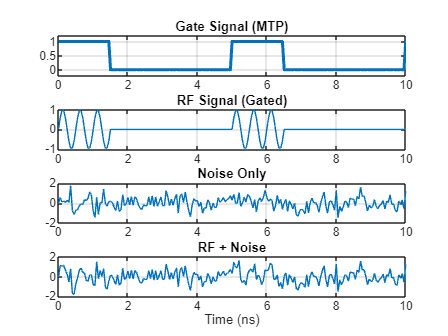


rf_norm = rf_plus_noise / scale;

rf_fixed = round(rf_norm * MAX_VAL);
subplot(5,1,5);
plot(t*1e9,rf_fixed);

% Clip
rf_fixed(rf_fixed >  MAX_VAL) =  MAX_VAL;
rf_fixed(rf_fixed < -MAX_VAL) = -MAX_VAL;

% Convert signed -> unsigned
rf_unsigned = rf_fixed + 2^(DATA_WIDTH-1);

% SANITY CHECK
fprintf('Unsigned min = %d, max = %d\n', ...
        min(rf_unsigned), max(rf_unsigned));

Unsigned min = 1, max = 3917




% WRITE MEM FILE (HEX)

fid = fopen('rf_noise.mem','w');

if fid == -1
    error('ERROR: Cannot create rf_noise.mem file');
end

for i = 1:length(rf_unsigned)
    fprintf(fid,'%03X\n', rf_unsigned(i));
end

fclose(fid);

fprintf('rf_noise.mem GENERATED SUCCESSFULLY\n');

rf_noise.mem GENERATED SUCCESSFULLY




% FINAL CHECK

fprintf('First 10 MEM values:\n');

First 10 MEM values:


disp(rf_unsigned(1:10));

         799        2473        2216        2750        3917        2067        2367         610        1923         617




fprintf('--- MATLAB SCRIPT COMPLETED ---\n');

--- MATLAB SCRIPT COMPLETED ---


clc;
clear;
close all;

fc = 2e9;            % RF carrier (simulation only)
Fs = 20e9;           % Sampling frequency
num_periods = 5;     % Number of radar pulses

total_samples = 100; % One PRI
on_samples    = 30;  % MTP ON
off_samples   = 70;  % MTP OFF

noise_power = 0.4;   % Noise power
DATA_WIDTH = 12;     % For COE


% TIME VECTOR

N = total_samples * num_periods;
t = (0:N-1)/Fs;

% GATE SIGNAL (MTP)

gate = repmat([ones(1,on_samples) zeros(1,off_samples)], 1, num_periods);

% RF SIGNAL

rf = sin(2*pi*fc*t);

% GATED RF

rf_gated = rf .* gate;

% NOISE

noise = sqrt(noise_power) * randn(1, N);

% RF + NOISE

rf_plus_noise = rf_gated + noise;

% PLOTTING

figure('Position',[100 100 1200 900]);

subplot(4,1,1);
plot(t*1e9, gate, 'LineWidth',2);
title('Gate Signal (MTP)');
ylim([-0.2 1.2]); xlim([0 10]);
grid on;

subplot(4,1,2);
plot(t*1e9, rf_gated);
title('RF Signal (Gated)');
xlim([0 10]);
grid on;

subplot(4,1,3);
plot(t*1e9, noise);
title('Noise Only');
xlim([0 10]);
grid on;

subplot(4,1,4);
plot(t*1e9, rf_plus_noise);
title('RF + Noise');
xlabel('Time (ns)');
xlim([0 10]);
grid on;

% COE FILE 1: GATE (MTP)

gate_unsigned = gate * (2^DATA_WIDTH - 1);  % 0 or max value

fid = fopen('gate.coe','w');
fprintf(fid,'memory_initialization_radix=10;\n');
fprintf(fid,'memory_initialization_vector=\n');
for i = 1:length(gate_unsigned)
    if i < length(gate_unsigned)
        fprintf(fid,'%d,\n', gate_unsigned(i));
    else
        fprintf(fid,'%d;\n', gate_unsigned(i));
    end
end
fclose(fid);

disp('gate.coe generated');


% COE FILE 2: RF + NOISE

MAX_VAL = 2^(DATA_WIDTH-1) - 1;

% Normalize safely
rf_norm = rf_plus_noise / max(abs(rf_plus_noise));

rf_fixed = round(rf_norm * MAX_VAL);
rf_fixed(rf_fixed >  MAX_VAL) =  MAX_VAL;
rf_fixed(rf_fixed < -MAX_VAL) = -MAX_VAL;

rf_unsigned = rf_fixed + 2^(DATA_WIDTH-1);

fid = fopen('rf_noise.coe','w');
fprintf(fid,'memory_initialization_radix=10;\n');
fprintf(fid,'memory_initialization_vector=\n');
for i = 1:length(rf_unsigned)
    if i < length(rf_unsigned)
        fprintf(fid,'%d,\n', rf_unsigned(i));
    else
        fprintf(fid,'%d;\n', rf_unsigned(i));
    end
end
fclose(fid);

disp('rf_noise.coe generated');